addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')

% Configuration file was changed on xlmcon and then files were processed
% using Leah's processing pipeline 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')


% Casts 
% cast07 = readSBScnv( 'AR21_007_bad_SBE43_data.cnv' );
% cast08 = readSBScnv( 'AR21_008_bad_SBE43_data.cnv' );
cast09 = readSBScnv( 'uAR21_009_hystabcdef.cnv' );
cast10 = readSBScnv( 'uAR21_010_hystabcdef.cnv' );
cast11 = readSBScnv( 'uAR21_011_hystabcdef.cnv' );
cast12 = readSBScnv( 'uAR21_012_hystabcdef.cnv' );

% cast09 = readSBScnv( 'uAR21_009_hyst.cnv' );
% cast10 = readSBScnv( 'uAR21_010_hyst.cnv' );
% cast11 = readSBScnv( 'uAR21_011_hyst.cnv' );
% cast12 = readSBScnv( 'uAR21_012_hyst.cnv' );


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')
btl = readtable('Irminger_Sea-04_AR21_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum07 = btl(btl.Cast == 07,:);
btlsum08 = btl(btl.Cast == 08,:);

btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year4')

btl07 = readtable('AR21_007_hyst.csv','TextType','string');

btl08 = readtable('AR21_008_hyst.csv','TextType','string');

btl10 = readtable('AR21_010_hyst.csv','TextType','string');

btl11 = readtable('AR21_011_hyst.csv','TextType','string');

btl12 = readtable('AR21_012_hyst.csv','TextType','string');


% Join tables 
btlsum07 = join(btl07,btlsum07,'Keys',"Bottle");
btlsum07.Sbeox0V(:,:) = NaN; % Remove SBE data before pump was changed
btlsum07.Sbeox0ML_L(:,:) = NaN;
btlsum08 = join(btl08,btlsum08,'Keys',"Bottle");
btlsum08.Sbeox0V(:,:) = NaN; % Remobe SBE data before pump was changed 
btlsum08.Sbeox0ML_L(:,:) = NaN;
btlsum10 = join(btl10,btlsum10,'Keys',"Bottle");
btlsum11 = join(btl11,btlsum11,'Keys',"Bottle");
btlsum12 = join(btl12,btlsum12,'Keys',"Bottle");

clear btl0* btl1* btl2* btl

btlsum_yr4 = [btlsum07; btlsum08; btlsum10; btlsum11; btlsum12];

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')
save Year4_Processed_KF cast* btl*

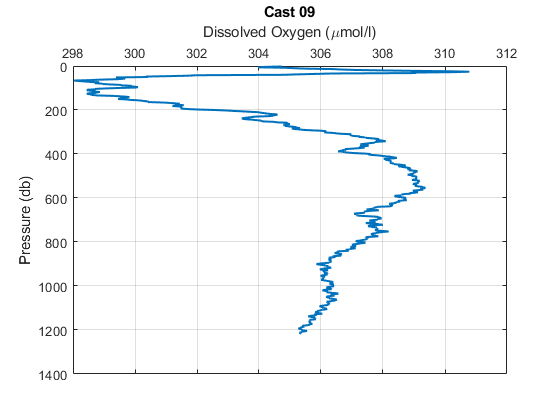

figure
plot(cast09.sbeox0mL_L*44.661,cast09.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 09')

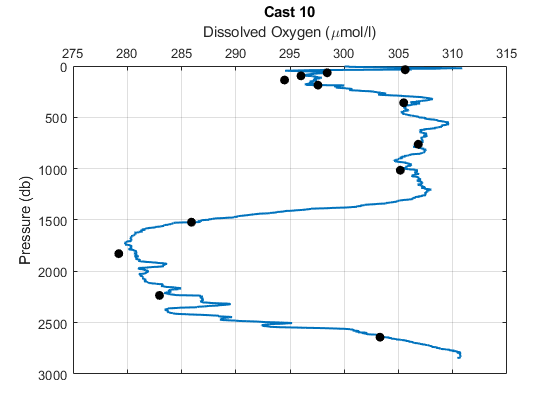


figure
plot(cast10.sbeox0mL_L*44.661,cast10.pm,'Linewidth',1.5)
hold on
plot(btlsum10.Winkler_mLL*44.661,btlsum10.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 10')

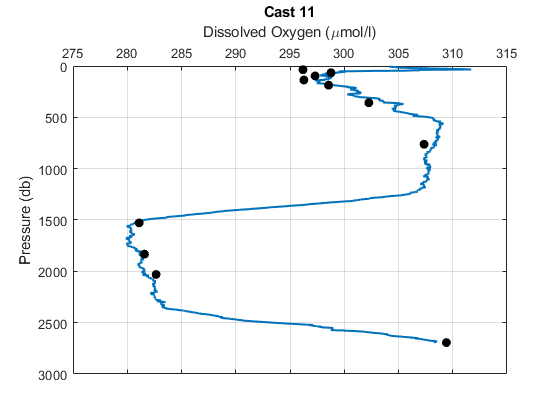


figure
plot(cast11.sbeox0mL_L*44.661,cast11.pm,'Linewidth',1.5)
hold on
plot(btlsum11.Winkler_mLL*44.661,btlsum11.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 11')

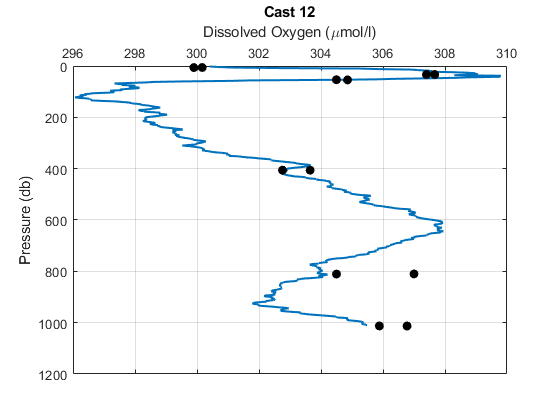


figure
plot(cast12.sbeox0mL_L*44.661,cast12.pm,'Linewidth',1.5)
hold on
plot(btlsum12.Winkler_mLL*44.661,btlsum12.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 12')